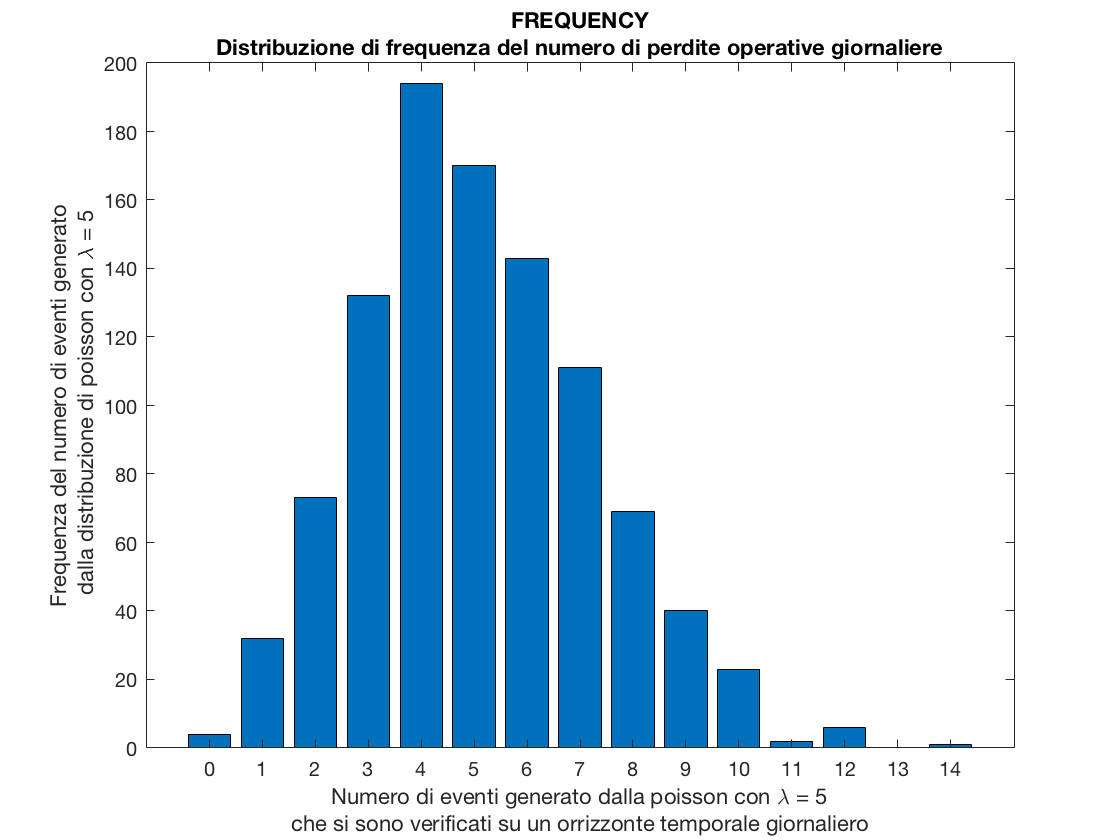

            % % % % % % PROGETTO Descrivere l’approccio attuariale alla misurazione del rischio 
% operativo
% % % clc
clear

% PARAMETRI A DISCREZIONE DELL'UTENTE. Questi, nel nostro caso, sono stati
% definiti nella consegna dell'approfondimento a noi assegnato.
mu=[1.5 1.5 3];
lambda=5;
var=[1 2 1];

% Calcoliamo la deviazione standard che verrà utilizzata nella funzione 
% lognrnd per generare valori casuali da una distribuzione log-normale 
% con parametri mu e sigma. La radice della varianza ci restituisce
% il valore desiderato.
sigma=sqrt(var);


% Definiamo il numero di ripetizioni della simulazione. All'aumentare di n
% la precisione della simulazione migliora e con essa la rappresentazione
% della distribuzione delle perdite diventa più affidabile, potendo far 
% affidamento su di un numero maggiore di scenari simulati.
% All'aumentare di n, però aumenta la quantità di lavoro computazionale.
n=1000;


% Definiamo alpha come il livello di confidenza per il calcolo del VAR. 
% Alpha è pari a 0.99 e dunque nel 99% dei casi la perdita che si 
% verificherà non supererà il valore L_Var trovato. Nel restante 1% dei casi 
% però, non ci sono informazioni a riguardo della possibile perdita.
alpha=0.99;


% Definiamo dunque il valore di frequency degli eventi di perdita. Lo facciamo
% estraendo valori casuali da una distribuzione di Poisson:
k = poissrnd(lambda,n,1);
% Usare la distribuzione di Poisson è utile perchè:
% 1) si possono aggregare più distribuzioni di Poisson legate ciascuna ad un
% determinato event type di rischio operativo all'interno di una determinata
% business line (a tal fine ci si poggia sull'ipotesi di indipendenza degli 
% eventi nei diversi sottoperiodi temporali) PROPRIETA' ADDITIVA;
% 2) è semplice da implementare, basta conoscere il numero medio di volte che
% l'evento si verifica in un arco di tempo (lambda) per definire l'intera 
% distribuzione.


% Definiamo le severity delle perdite operative effetuando estrazioni 
% casuali da una distribuzione log-normale.
s=1;
% Calcoliamo i valori di massimo e di minimo di k:
max=max(k);
min=min(k);
% settiamo la matrice delle severity (X) come una matrice di zeri di dimensioni 
% max per il numero di righe e cioè al massimo valore assunto da x e n per le 
% colonne cioè pari al numero di valori di frequency estratti. Abbiamo dunque:
x=zeros(max,n);
% Andiamo a riempire questa matrice con i valori di severity of loss.
% Lo facciamo tramite un triplo ciclo for.Il ciclo calcola le perdite operative 
% sulla base di valori casuali generati da una distribuzione log-normale con 
% parametri definiti per 3 diversi scenari. I valori di ogni colonna della matrice
% x, vengono sommati calcolando così la perdita L legata all'i-esimo event type 
% e alla j-esima business line. Il ciclo viene ripetuto n volte permettendo
% così la definizione della distribuzione di perdita: 
for p=1:3
    for i=1:n
        x(1:k(i),s)=lognrnd(mu(p),sigma(p),k(i),1);
        s=s+1;     
        if s==n+1
            s=1;
            break
        end
    end
    % Calcolo della perdita operativa legata all'i-esimo event type nella j-esima 
    % business line come somma delle k perdite Xi:
    L(p,:)=sum(x); 
    % Ordiniamo le perdite L per poter successivamente costruire l'istogramma
    % con le frequenze degli intervalli di perdita.
    L_sort(p,:)=sort(L(p,:));
    % Calcolo del VAR con un livello di confidenza del 99% (alpha)
    L_var(p)=quantile(L_sort(p,:),alpha);
end


% Calcoliamo il valore atteso di perdita (Expected Loss):
L_mean=mean(L');

% Calcolo del Capital at Risk come differenza tra il Var calcolato come 99°
% quantile della distribuzione di L e il valore atteso delle perdita:
C_ar=L_var-L_mean;


% Costruzione di un bar chart raffigurante i valori di frequency of Loss.
% Definiamo una frequenza di valori contenuti tra il minimo ed il massimo di k,
% con uno spazio unitario tra un valore e l'altro.
edges = min:1:max;

% Contiamo i valori contenuti in edges che si osservano nel vettore k.
% Costruiamo il grafico a barre contenente la frequenza dei valori di frequency.
m= histc(k,edges);
bar(edges,m);

% Integrazione del grafico con legenda e descrizione degli assi
title({'FREQUENCY','Distribuzione di frequenza del numero di perdite operative giornaliere'});
ylabel({'Frequenza del numero di eventi generato',[' dalla distribuzione di poisson con \lambda = ' num2str(lambda)]});
xlabel({['Numero di eventi generato dalla poisson con \lambda = ' num2str(lambda)],'che si sono verificati su un orrizzonte temporale giornaliero'});

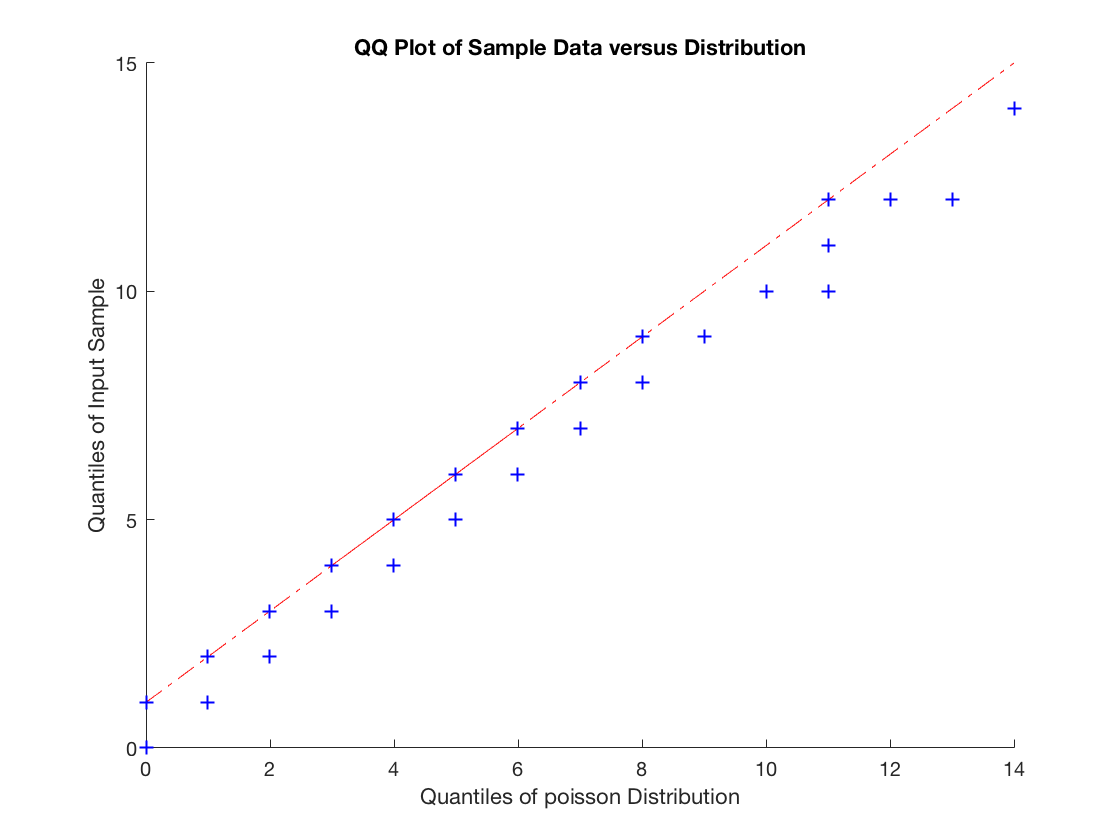



% Costruzione di un qqplot utile per verificare se la distribuzione teorica 
% utilizzata, in questo caso una poissoniana, approssima correttamente i 
% valori di k. Nel nostro caso, avendo definito i valori di K attraverso estrazioni
% casuali da una distribuzione di Poisson, l'approssimazione della distribuzione empirica
% con quella teorica risulterà corretta.
qqplot(k,makedist('Poisson','lambda',5))

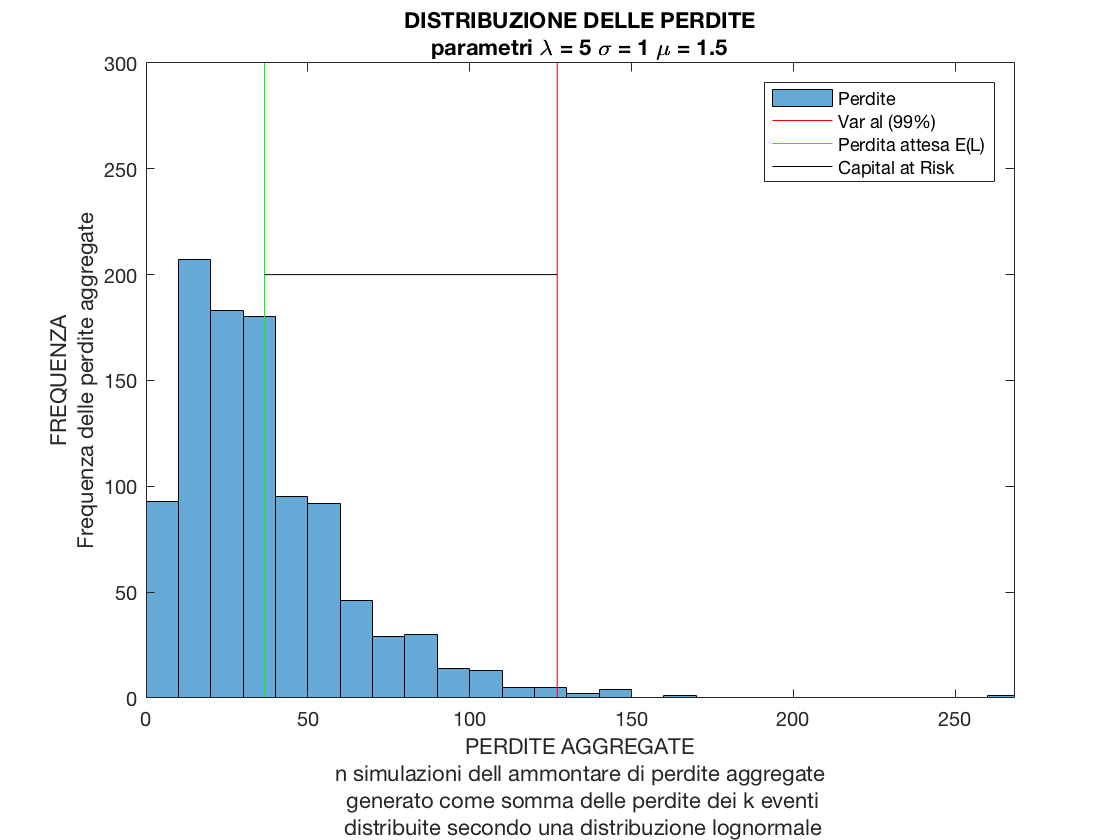



% Costruzione dell'istogramma rappresentante la distribuzione di perdita (L)
% per 3 diversi scenari con diversi parametri mu e sigma.
% Nel grafico è rappresentato il VAR al 99%, come 99° quantile della 
% distribuzione continua delle perdite, e il valore atteso delle perdite come
% media delle n simulazioni. La differenza rappresenta il Capital at Risk,
% cioè il capitale che la banca rischia di perdere a causa delle perdite inattese.
% PRIMO CASO: lambda = 5 mu = 1.5 sigma = 1
histogram(L_sort(1,:));
title({'DISTRIBUZIONE DELLE PERDITE',['parametri \lambda = ' num2str(lambda) ' \sigma = ' num2str(sigma(1)) ' \mu = ' num2str(mu(1))]});
hold on
plot([L_var(1),L_var(1)],[0 300],'r');
plot([L_mean(1),L_mean(1)],[0 300],'g');
plot([L_mean(1),L_var(1)],[200 200],'k');
legend('Perdite','Var al (99%)','Perdita attesa E(L)','Capital at Risk');
axis([0 L_sort(1,end) 0 300])
ylabel({'FREQUENZA','Frequenza delle perdite aggregate'});
xlabel({'PERDITE AGGREGATE','n simulazioni dell ammontare di perdite aggregate',' generato come somma delle perdite dei k eventi',' distribuite secondo una distribuzione lognormale'});
hold off

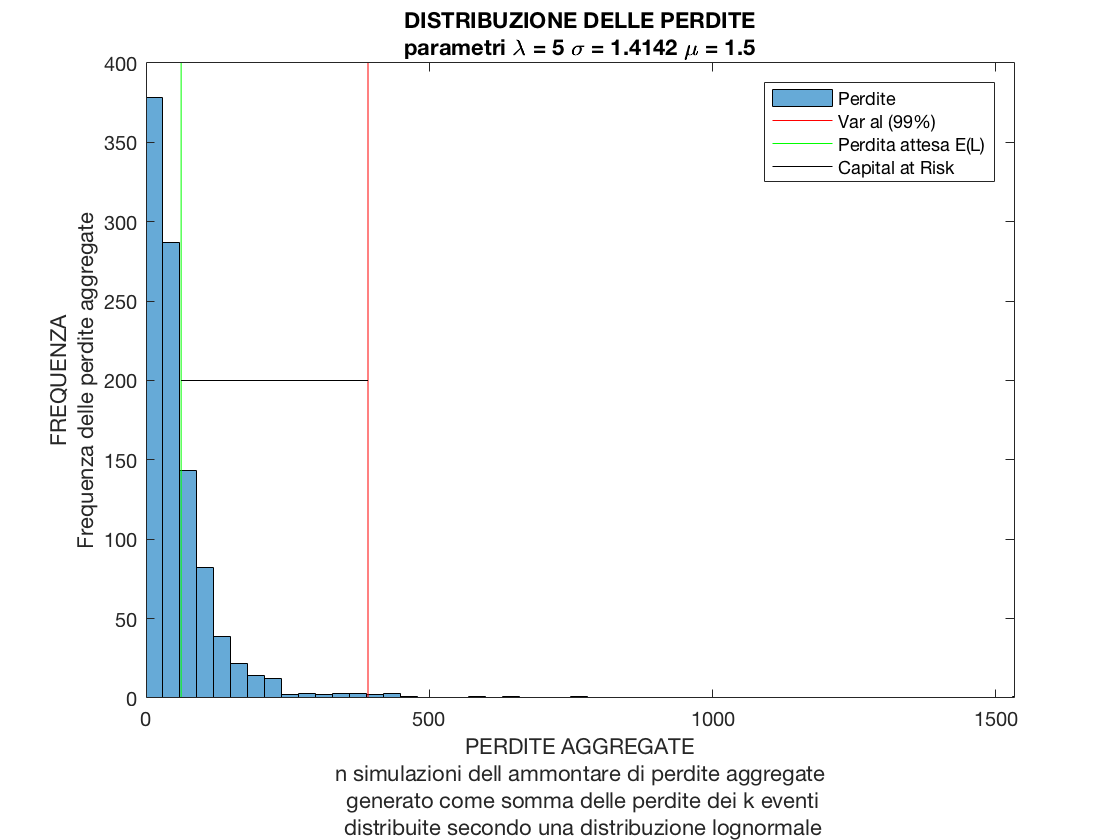

% SECONDO CASO: lambda = 5 mu = 1.5 sigma = 1.4142
histogram(L_sort(2,:));
title({'DISTRIBUZIONE DELLE PERDITE',['parametri \lambda = ' num2str(lambda) ' \sigma = ' num2str(sigma(2)) ' \mu = ' num2str(mu(2))]});
hold on
plot([L_var(2),L_var(2)],[0 400],'r');
plot([L_mean(2),L_mean(2)],[0 400],'g');
plot([L_mean(2),L_var(2)],[200 200],'k');
legend('Perdite','Var al (99%)','Perdita attesa E(L)','Capital at Risk');
axis([0 L_sort(2,end) 0 400])
ylabel({'FREQUENZA','Frequenza delle perdite aggregate'});
xlabel({'PERDITE AGGREGATE','n simulazioni dell ammontare di perdite aggregate',' generato come somma delle perdite dei k eventi',' distribuite secondo una distribuzione lognormale'});
hold off

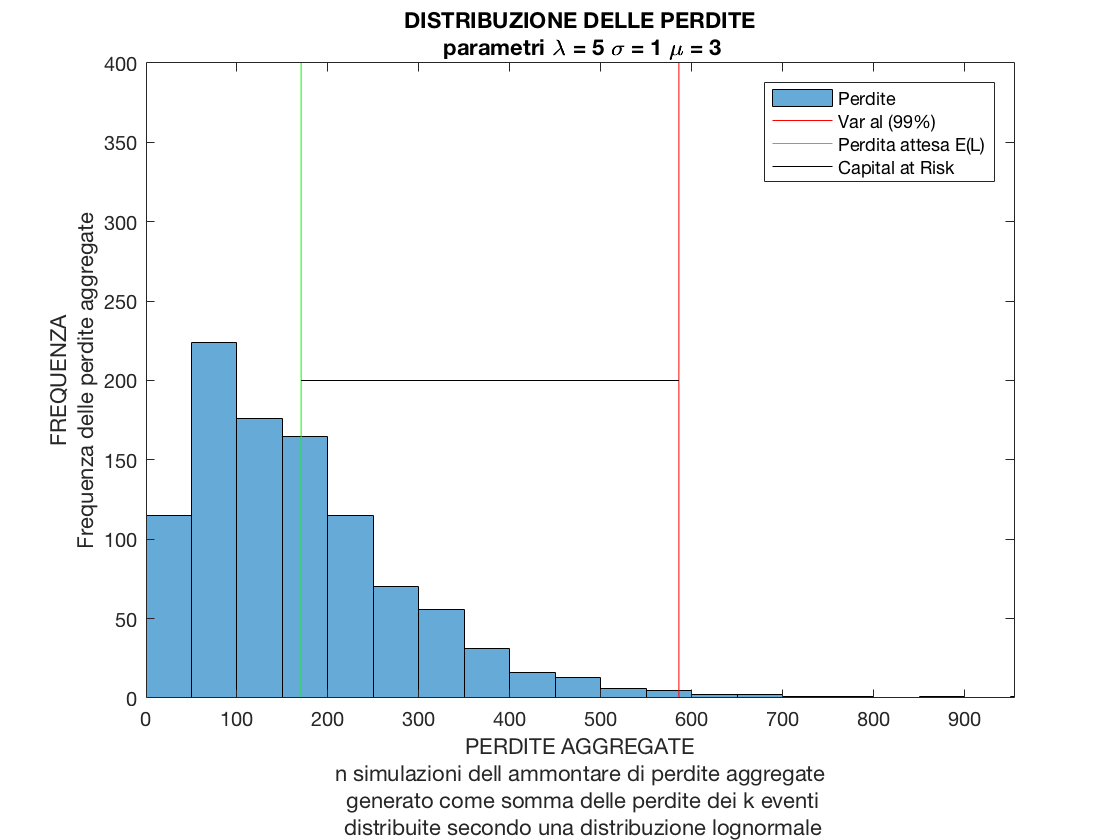

% TERZO CASO: lambda = 5 mu = 3 sigma = 1
histogram(L_sort(3,:));
title({'DISTRIBUZIONE DELLE PERDITE',[' parametri \lambda = ' num2str(lambda) ' \sigma = ' num2str(sigma(3)) ' \mu = ' num2str(mu(3))]});
hold on
plot([L_var(3),L_var(3)],[0 400],'r');
plot([L_mean(3),L_mean(3)],[0 400],'g');
plot([L_mean(3),L_var(3)],[200 200],'k');
legend('Perdite','Var al (99%)','Perdita attesa E(L)','Capital at Risk');
axis([0 L_sort(3,end) 0 400])
ylabel({'FREQUENZA','Frequenza delle perdite aggregate'});
xlabel({'PERDITE AGGREGATE','n simulazioni dell ammontare di perdite aggregate',' generato come somma delle perdite dei k eventi',' distribuite secondo una distribuzione lognormale'});
hold off